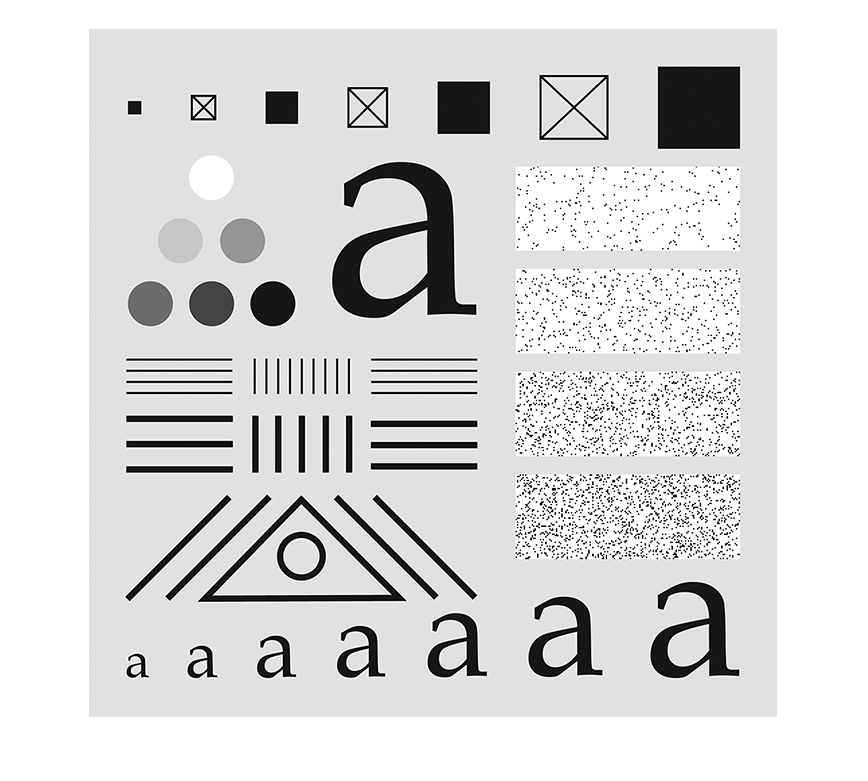

%1
Image=im2double(imread('TestPattern.tif'));
imshow(Image);

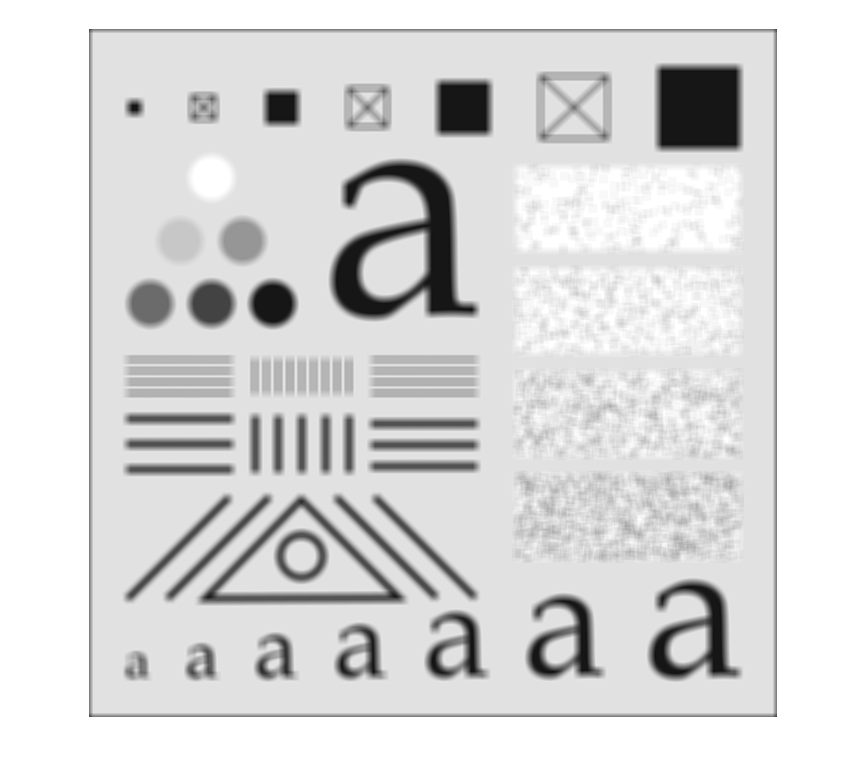


kernel = ones(9,9)/(9*9);

Image1 = imfilter(Image, kernel);
imshow(Image1);

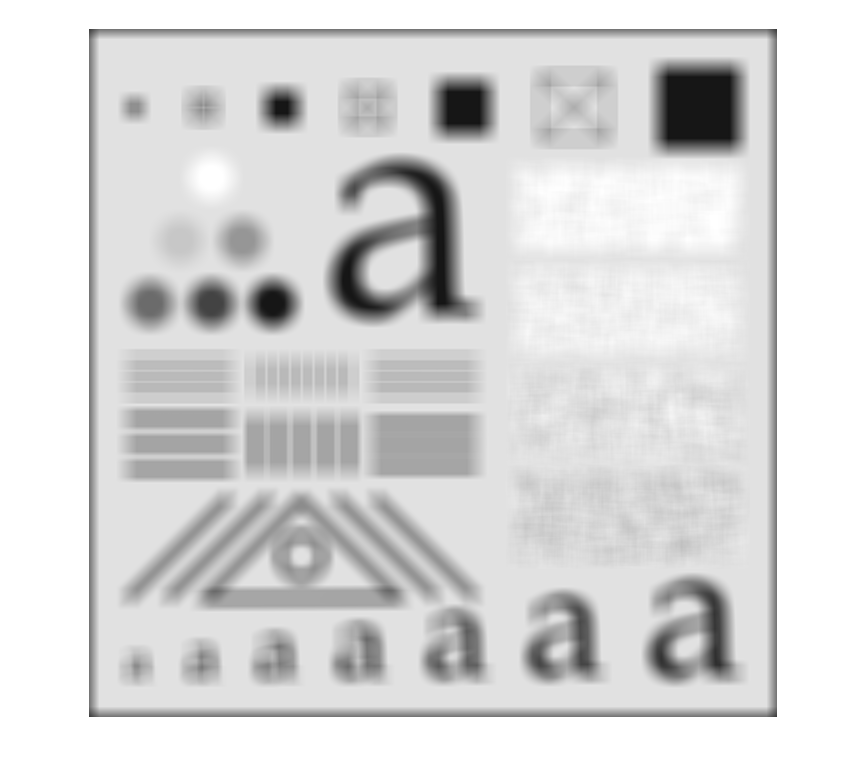

%2
Image=im2double(imread("TestPattern.tif"));

kernel = ones(21)/(21*21);

Image2 = imfilter(Image, kernel);
imshow(Image2);

%3
%Högre cutoff frequency då normaliceringen blir ett mindre tal

%4
%på grund av zero-padding.

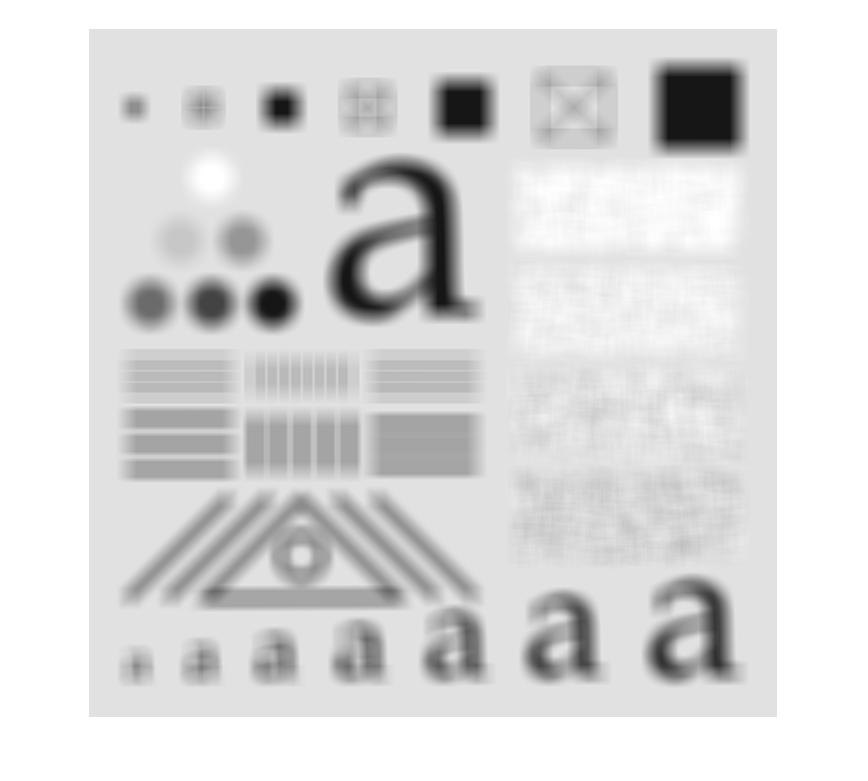

%5
Image=im2double(imread("TestPattern.tif"));

kernel = ones(21)/(21*21);

Image1 = imfilter(Image, kernel);

Image3 = imfilter(Image, kernel, 'symmetric');
imshow(Image3);

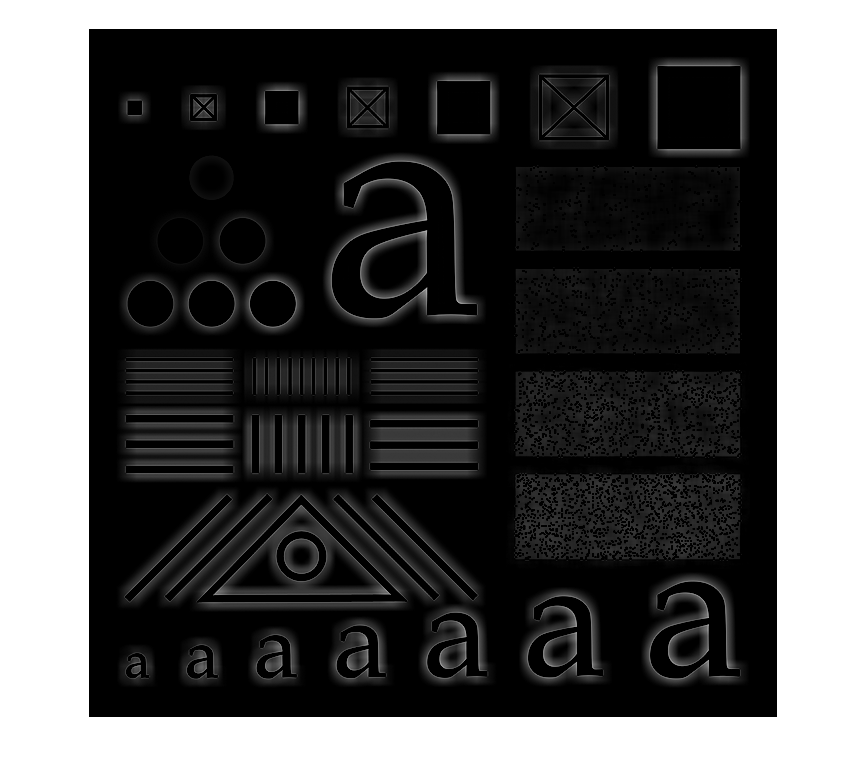

%6
Image=im2double(imread("TestPattern.tif"));
kernel = ones(21)/(21*21);

m = zeros(21);
m(11,11) = 1;

highpass = m-kernel;
Image4 = imfilter(Image, highpass, 'symmetric');
imshow(Image4);

%7
% Because we are now filtering with a highpass filter
%Vet inte svaret på denna, Richard leta du
%borde vara q x q med average styrka Q  
% Se fråga 19 på lektion
mGray = mean2(Image4);

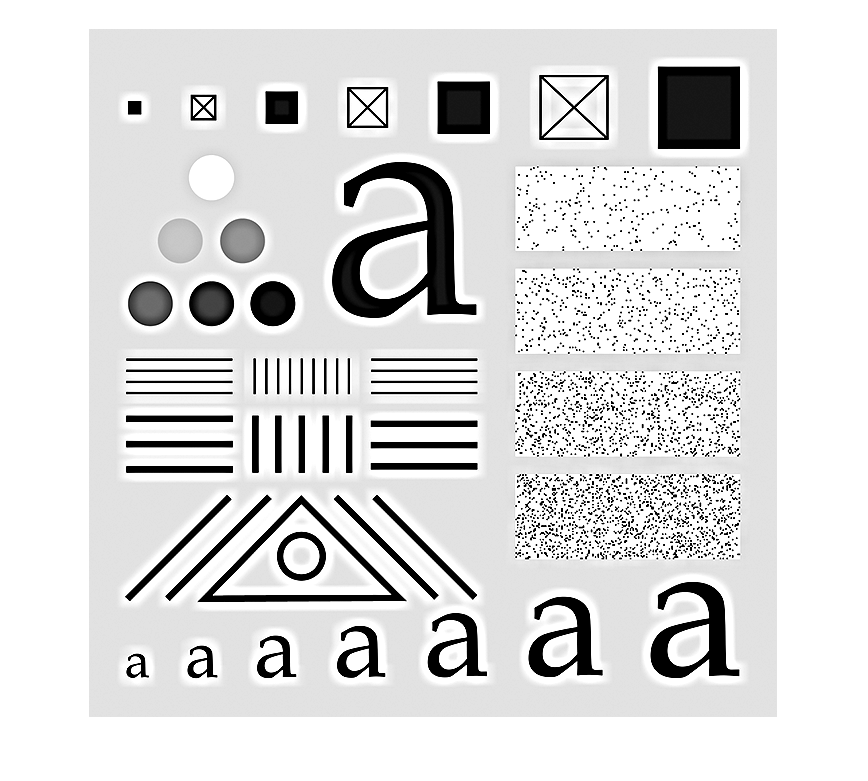

%8
Image5= Image + Image4;
imshow(Image5);

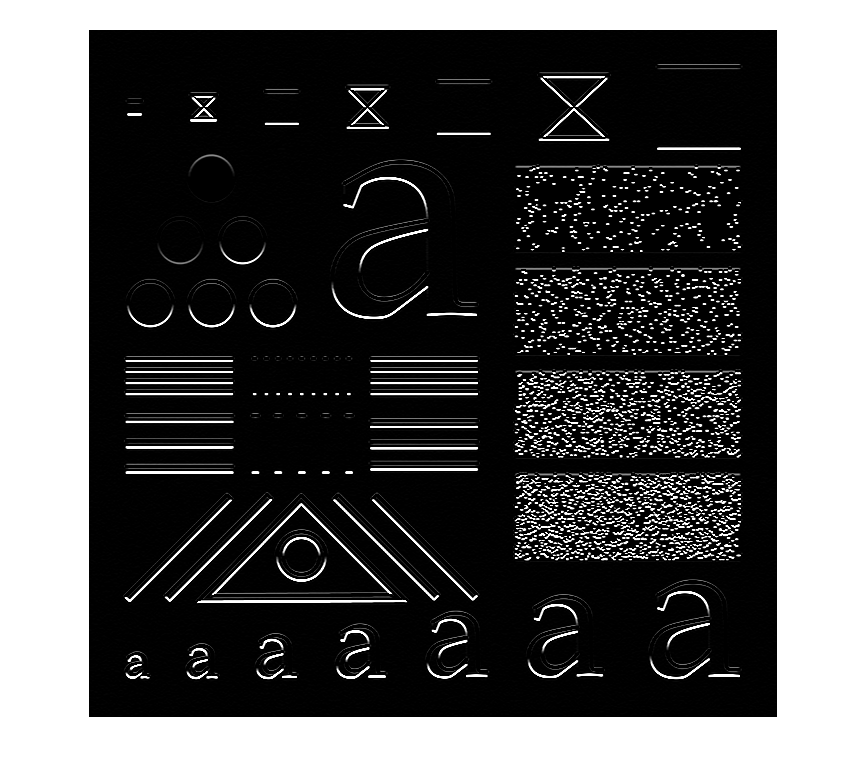

%9
Image = im2double(imread("TestPattern.tif"));
Sobx = [-1 -2 -1; 0 0 0; 1 2 1];

Image6 = imfilter(Image, Sobx);
imshow(Image6) 

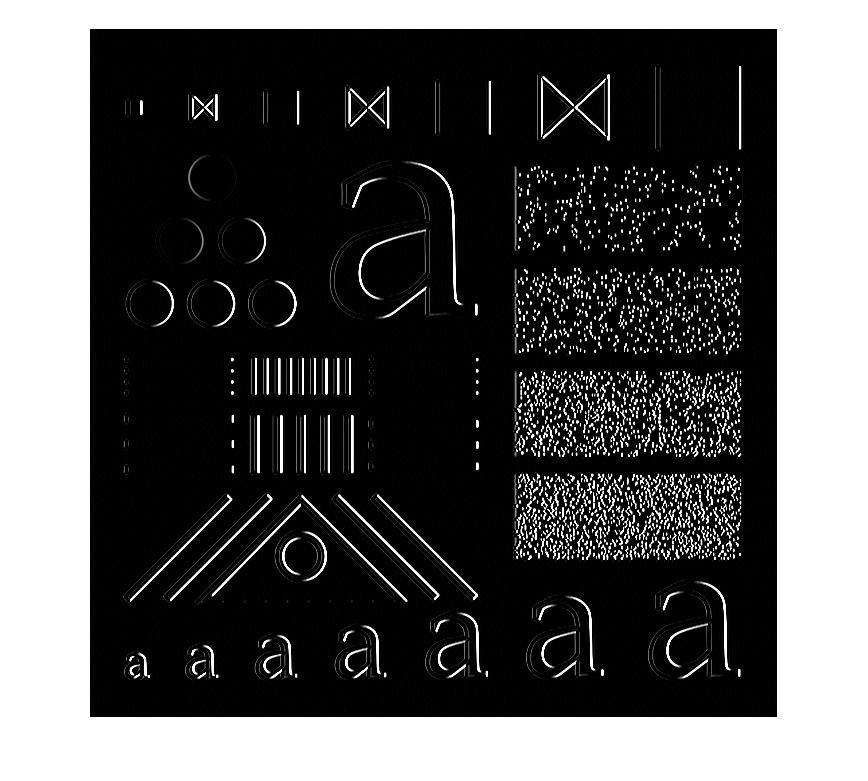

%10
Image = im2double(imread("TestPattern.tif"));
Soby = [-1 0 1; -2 0 2; -1 0 1];
Image7 = imfilter(Image, Soby);
imshow(Image7)

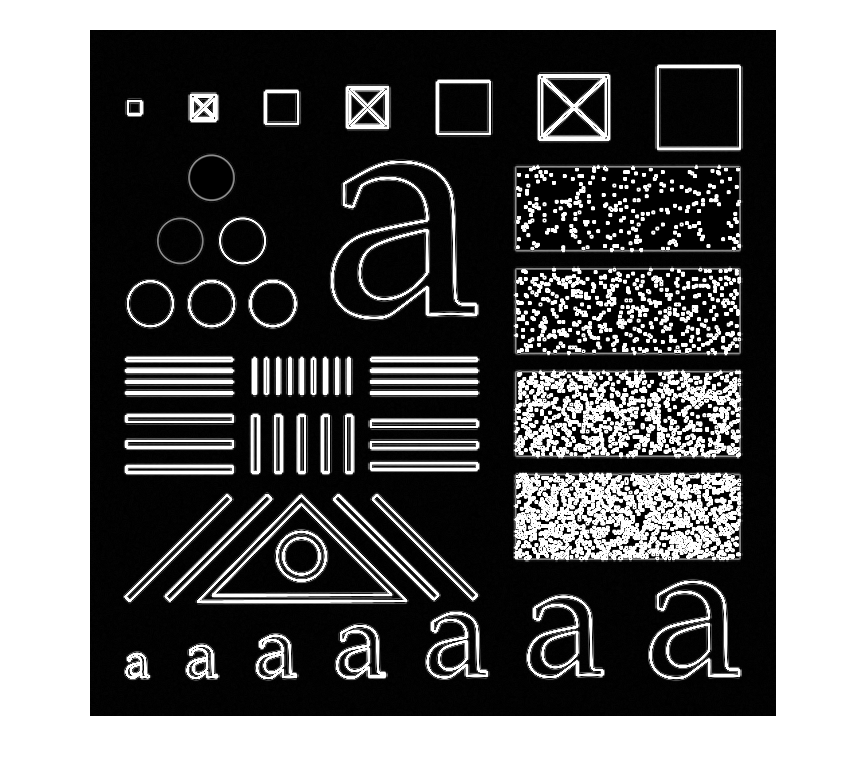

%11
Image8 = sqrt((Image6.^2 + Image7.^2));
imshow(Image8);

%myfilter

Image_test1 = im2double(imread("TestPattern.tif"));
Image_test2 = im2double(imread("zoneplate.tif"));
Image_test3 = im2double(imread("test1.tif"));
Image_test4 = im2double(imread("test2.tif"));
Image_test5 = im2double(imread("test3.tif"));
Image_test6 = im2double(imread("test4.tif"));
BoxKernal1 = ones(9)/(9*9);
BoxKernal2 = ones(21)/(21*21);